# Try the cwtLayer

XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;

XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};

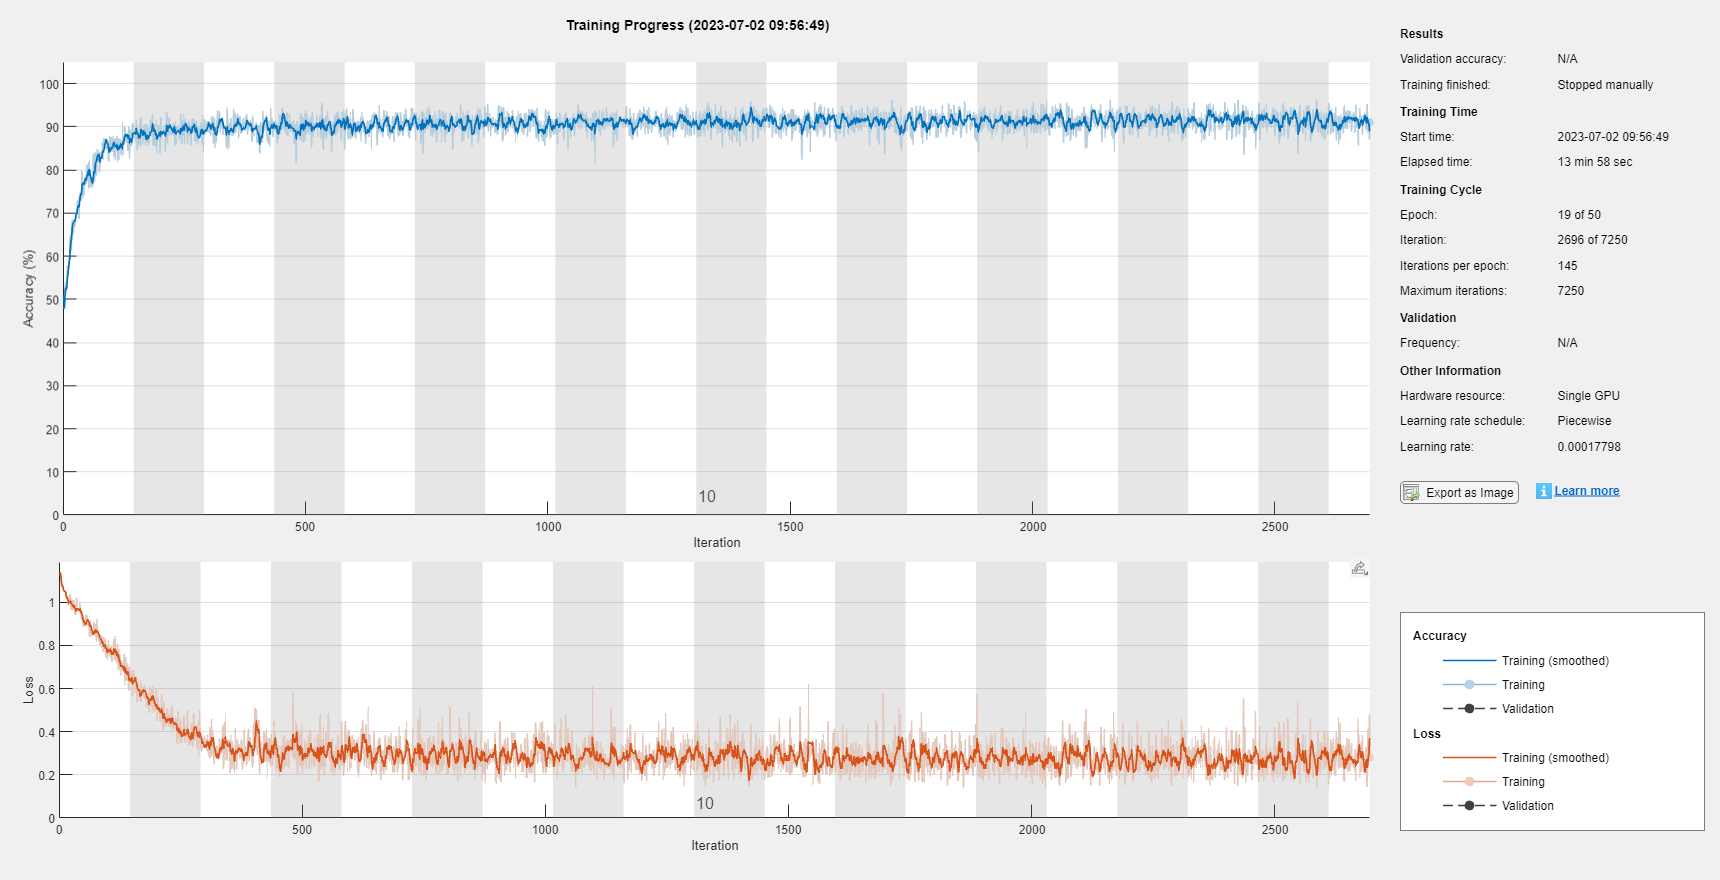

rng(1);

% layers = constructCWTCNN(3);

layers = CWTCovMixer(3, "classes",{
    {'blink'          }
    {'n/a'            }
    {'muscle-artifact'}}); % try the https://github.com/matlab-deep-learning/convmixer-patches-are-all-you-need/blob/master/convmixer/convMixerLayers.m

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'MiniBatchSize',32, ...
    'InitialLearnRate',1e-3, ...
    'LearnRateDropPeriod',3, ...
    'L2Regularization',0.001,...
    'LearnRateDropFactor',0.75, ...
    'LearnRateSchedule','piecewise', ...
    'Plots','training-progress',...
    'GradientThreshold',1, ...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true);

% 
net = trainNetwork(XTrain,YTrain,layers,options);


YPred = classify(net, XTest, "MiniBatchSize",32);

%%%%%%%%%%%%%%%%%
valError = 0;
for k = 1:length(YPred)
    % fix this
    valError = valError + mean(YPred{k} == YTest{k});
end
% return a numeric scalar
accuracy =valError/length(YPred)

accuracy = 0.9121